# Get firing probabilities with respect to SWRs and theta waves

This analysis is aimed at seeing how each of the neurons we are recording from is firing with respect to different phases of the theta oscillations and different timepoints within a SWR. 

The firing of the cells around SWRs and at different phases of the theta oscillations is calculated. Other information is included as well e.g., firing rate, waveform, site (from MRI). 

If the analysis has already been performed, (1) clear all the data and (2) run only the first 4 cells to load the data needed for the plots. 

March 2023, Athina Apostolelli and Peter Gombkoto

## Set parameters

sessname = '6_240205_150311';
animal = 'rEO_06';
pyramidal_layer_left = 4;
pyramidal_layer_right = 12;
sample_rate_LFP = 2000;
sample_rate = 20000;
forceReload = false;  % to recalculate SWR and theta firing

basepath = fullfile('I:\Dropbox (Yanik Lab)\Localization Manuscript 2024\RAT DATA', animal, sessname);
cd(basepath)
lfp_path = 'C:\Users\RECORDING\Athina\Ripples\lfp_data';
lfp_file = fullfile(lfp_path, animal, [sessname, '.amplifier_ds.lfp']);  % downsampled to 2000 Hz
ripple_path = 'C:\Users\RECORDING\Athina\Ripples\curated_ripples';
ripple_file = fullfile(ripple_path, animal, sessname, 'curated_ripples.mat');

% Output directory
plotpath = fullfile(basepath, 'FiringCorrelations');
if ~isfolder(plotpath)
    mkdir(plotpath);
end

## Import data 

Note: the cluster site here is the site given by JRClust, where the waveform is maximum. On the channel map, this is -1 because of differences in indexing. 

Note: for the waveforms, the filtered data should be imported. It seems that the indexing of JRClust for the raw and the filtered waveforms are different. What is displayed during manual curation are the filtered data, so we are sticking to that. 

% LFP
if exist(lfp_file)
    LFP = ImporterDAT_multi(lfp_file, 16, [1:16]);  % filename, total_channels, channels
else
    disp('The LFP file does not exist in this directory.');
    return
end

% SWRs
if exist(ripple_file)
    ripples = load(ripple_file);
    ripple_timestamps = ripples.ripple_timestamps;
    ripple_classes = ripples.ripple_classes;
    num_ripples = length(ripple_classes);
else
    disp('The curated ripple file (CNN detection) does not exist in this directory.');
    return
end

% Spikes
spikes = loadSpikes_JRC('basepath',basepath,'forceReload',false);

loadSpikes: Loading JRClust data
Loading shank #1/2
Loading shank #2/2
Saving spikes.


num_neurons = length(spikes.UID);

% Spiking and electrode data
[rawRecordings,sampleRate,bitScaling,shankMap,siteMap,siteLoc,probePad] = read_prb_file; % read paramater about the electrode, and raw data file.
load(fullfile(basepath, 'amplifier_res.mat'), 'spikeTimes');
load(fullfile(basepath, 'amplifier_res.mat'), 'spikeClusters');
load(fullfile(basepath, 'amplifier_res.mat'), 'clusterSites');

% Waveforms
fid=fopen(['amplifier_filt.jrc'],'r');
filtWaveforms = fread(fid,Inf,'int16');   % spike waveform filtered by JRClust raw data from binary
fclose(fid);

spike_window = [-0.25, 1.5];
waveforms = getWaveformsNew(filtWaveforms,'basepath',basepath,'sample_rate',sample_rate,'event_window',spike_window,'numcells',num_neurons);

% Theta firing
if exist(fullfile(basepath, [sessname '.theta_firing_binsize20.cellinfo.mat'])) & ~forceReload
    disp('Loading theta firing...');
    load(fullfile(basepath, [sessname '.theta_firing_binsize20.cellinfo.mat']));
end

Loading theta firing...


num_theta_bins = 18; % bin size = 20 degrees
bin_edges_theta = linspace(-180, 180, num_theta_bins+1);

% SWR firing
if exist(fullfile(basepath, [sessname '.swr_firing.cellinfo.mat'])) & ~forceReload
    disp('Loading SWR firing...');
    load(fullfile(basepath, [sessname '.swr_firing.cellinfo.mat']));
end

Loading SWR firing...


num_shuffles = 100; % per neuron

% Firing rates and channel map info
if exist(fullfile(basepath, [sessname '.fr_mapElastic_info.cellinfo.mat'])) & ~forceReload
    disp('Loading firing rate and channel map info...');
    load(fullfile(basepath, [sessname '.fr_mapElastic_info.cellinfo.mat']));
end

Loading firing rate and channel map info...



% Theta info (LFP filtered for theta, theta phase, theta windows, frequencies)
if exist(fullfile(basepath, [sessname '.theta_info.mat']))  & ~forceReload
    disp('Loading theta info...');
    load(fullfile(basepath, [sessname '.theta_info.mat']));
    new_theta_windows = theta_info.theta_segments;
    num_theta_windows = length(new_theta_windows);
end

Loading theta info...


## Process LFP  

Create a time vector that can be used to better estimate the indices of different events later on, and filter the LFP to detect the peak of the ripple in a SWR. 

% Helper time vector
FileInfo = dir(lfp_file);
nChansInRawFile=16; % selected LFP
num_samples = FileInfo.bytes/(nChansInRawFile * 2);

% Filter LFP
d = designfilt('bandpassfir','FilterOrder',600,'StopbandFrequency1',125,'PassbandFrequency1',130,'PassbandFrequency2',245,'StopbandFrequency2',250,'SampleRate',2000);
LFP_detrended = detrend(double(LFP')); % raw
LFP_filtered = filtfilt(d, LFP_detrended); % ripples
LFP_filtered_hilbert = abs(hilbert(LFP_filtered)); % hilbert transform

## Extract LFP from selected channels

Here we are selecting the raw data from specific channels.

Note: The LFP data originates from the original *.dat recordings from both the left and right hippocampus. Theta oscillations are particularly strong in the stratum radiatum, but they exhibit an opposite phase compared to those in the stratum pyramidale, which may lead to complications. Here we are focusing on theta oscillations from the pyramidal layer, even though they are not as pronounced there.

% Raw data info
filename = fullfile(basepath, 'amplifier.dat')

filename = 'I:\Dropbox (Yanik Lab)\Localization Manuscript 2024\RAT DATA\rEO_06\6_240205_150311\amplifier.dat'

% filename = 'amplifier.dat';
FileInfo = dir(filename);
nChansInRawFile = 128;
num_samples = FileInfo.bytes/(nChansInRawFile * 2); % int16 = 2 bytes

% Helper time vector
% time2=linspace(0,(num_samples./sample_rate),ceil((num_samples./sample_rate)/(bin/1000)));
time2 = linspace(0, (num_samples./sample_rate), ceil((num_samples./sample_rate)));

% % Selected time points for correlation matrix; % Note: interesting_segment 83.080sec 9th recording rEO_06
% start_theta = 53.241; % sec
% stop_theta = 101.109; % sec

% Loading selected channels
selectedChannels = [93, 37]+1; % LEFT - RIGHT Channels from Str.Pir. Number from Neuroscope
% Map the binary file into memory
% RowDat_map_memory_file = memmapfile(char(rawRecordings), 'Format', 'int16');
RowDat_map_memory_file = memmapfile(char(filename), 'Format', 'int16');

% Calculate the total number of samples per channel
% Note: The total number of data points divided by the number of channels gives the samples per channel
totalDataPoints = numel(RowDat_map_memory_file.Data);
samplesPerChannel = totalDataPoints / nChansInRawFile;

% Initialize a matrix to hold the data from the selected channels
LFPFromSelectedChannels = zeros(numel(selectedChannels), samplesPerChannel, 'int16');

% Extract data for each selected channel
for i = 1:numel(selectedChannels)
    channelIdx = selectedChannels(i);
    disp(channelIdx)
    LFPFromSelectedChannels(i,:) = RowDat_map_memory_file.Data(channelIdx:nChansInRawFile:end);

    % Update and display the loading progress
    % progressPercentage = (i / numel(selectedChannels)) * 100;
    % fprintf(['Loading channel#' num2str(channelIdx) ' %.2f%%\n'], progressPercentage);
end

    94
    38


fprintf('Data loading complete.\n');

Data loading complete.



% At this point, LfpFromSelectedChannels contains the data from your selected channels
% with each row corresponding to one of the channels.
LFPFromSelectedChannels = double(LFPFromSelectedChannels).*bitScaling;  % The smallest voltage step the ADC can resolve – also called the least significant bit (LSB) – is (2.45 V) / (216) = 37.4 μV.  Dividing this LSB level by the RHD2000 amplifier gain of 192
Time_vector_LFP = linspace(0,num_samples./sampleRate,length(LFPFromSelectedChannels));

## Import channel map 

filename = 'I:\Dropbox (Yanik Lab)\Localization Manuscript 2024\RAT DATA\rEO_06\MRI_ANALYSED\elastic_map\rEO_06-Elastic_chMap.txt';
% filename = 'I:\Dropbox (Yanik Lab)\Localization Manuscript 2024\RAT DATA\rEO_05\MRI_ANALYSED\affine\rEO_05-Affine_chMap.txt';
fileID = fopen(filename, 'r');
data = textscan(fileID, '%s', 'Delimiter', '\n');
fclose(fileID);

lines = data{1};
num_lines = numel(lines);
site = zeros(num_lines, 1);
channel = zeros(num_lines, 1);
location = cell(num_lines, 1);
segment_number = zeros(num_lines, 1);

% Parse each line
for i = 1:num_lines
    line = lines{i};
    parts = regexp(line, 'CH:(\d+) in (.+) Segment: (\d+\.?\d*)', 'tokens');
    if ~isempty(parts)
        site(i) = str2double(parts{1}{1})+1; % original site number 0-idx, here we switch to 1-idx to match JRC
        channel(i) = str2double(parts{1}{1}); % original channel
        location{i} = parts{1}{2};
        segment_number(i) = str2double(parts{1}{3});
    end
end

for c = 1:num_neurons
    area = location(site == siteMap(clusterSites(c)));
    if ~isempty(area) % visible electrode
        fr_map_info.site(c) = siteMap(clusterSites(c));
        fr_map_info.channel(c) = channel(site == siteMap(clusterSites(c)));
        fr_map_info.location{c} = area;
        fr_map_info.segment(c) = segment_number(site == siteMap(clusterSites(c)));
    else
        fr_map_info.site(c) = siteMap(clusterSites(c));
        fr_map_info.channel(c) = NaN;
        fr_map_info.location{c} = NaN;
        fr_map_info.segment(c) = NaN;
    end
end

## Theta analysis 

#### 1. Get the theta state according to the spectrogram

% Find theta epochs
freqlist = [2,20];  % 2-20 Hz
window = 2; % sec
noverlap = window - 1;
f_theta = [6 10];
f_delta = [2 3];

theta_windows = getThetaStates(LFPFromSelectedChannels,'freqlist',freqlist,'window',window,'noverlap',noverlap, ...
    'num_samples',num_samples,'sample_rate',sample_rate,'f_theta',f_theta,'f_delta',f_delta);
num_theta_windows = length(theta_windows);

#### 2. Extract theta phase 

[thetaPhase, thetaLFP] = getThetaPhase(LFPFromSelectedChannels, 'sample_rate',sampleRate, 'f_theta',f_theta);

#### 3. Remove segments with weak theta

% Find moments where theta is not strong and remove them
new_theta_windows = postprocessThetaSegments(theta_windows, LFPFromSelectedChannels, thetaLFP, thetaPhase, 'phase_threshold',15, ...
    'sample_rate',sample_rate, 'num_samples',num_samples, 'duration_threshold',0.5);

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1

ans = logical
   1


num_theta_windows = length(new_theta_windows);

theta_info.freqs = f_theta;
theta_info.theta_segments = new_theta_windows;
theta_info.thetaLFP = thetaLFP;
theta_info.thetaPhase = thetaPhase;
save(fullfile(basepath, [sessname '.theta_info.mat']),'theta_info');

#### 4. Bin firing relative to theta phase

The firing probability is the sum of spikes for each phase bin divided by the sum of spikes during the chosen theta segment. 

% start_theta_sample = arrayfun(@(idx) min(find(theta_windows(idx,1) < Time_vector_LFP & Time_vector_LFP < theta_windows(idx,2))), ...
%     1:num_theta_windows, 'UniformOutput', false);
% stop_theta_sample = arrayfun(@(idx) max(find(theta_windows(idx,1) < Time_vector_LFP & Time_vector_LFP < theta_windows(idx,2))), ...
%     1:num_theta_windows, 'UniformOutput', false);

p_theta = zeros(num_neurons, 1);
theta_spikes = zeros(num_neurons, num_theta_bins);
theta_firing_prob = zeros(num_neurons, num_theta_bins);

for c = 1:num_neurons
    % Convert spike times from seconds to sample indices
    spikeIndices = double(spikeTimes(spikeClusters == c));

    % Extract spikes by the start-stop of the theta
    % spikeIndices_selected = arrayfun(@(idx) spikeIndices(find(start_theta_sample{idx} < spikeIndices & spikeIndices < stop_theta_sample{idx})), ...
    %     1:length(theta_windows), 'UniformOutput', false);
    spikeIndices_selected = arrayfun(@(idx) spikeIndices(new_theta_windows(idx,1) < spikeIndices & spikeIndices < new_theta_windows(idx,end)), ...
        1:num_theta_windows, 'UniformOutput', false);

    % Extract theta phase at each spike time
    theta_spike_phases = [];
    win_spikes = zeros(num_theta_windows, num_theta_bins);
    win_firing_prob = zeros(num_theta_windows, num_theta_bins);

    for w = 1:num_theta_windows
        if ~isempty(spikeIndices_selected{w})
            if clusterSites(c) < 65
                spikePhases = thetaPhase(spikeIndices_selected{w},2); % right shank
            else
                spikePhases = thetaPhase(spikeIndices_selected{w},1); % left shank
            end
            win_spikes(w,:) = histcounts(spikePhases, bin_edges_theta);
            win_firing_prob(w,:) = win_spikes(w,:) ./ length(spikeIndices_selected{w});
            theta_spike_phases = [theta_spike_phases spikePhases'];
        end
    end
    theta_phases{c} = theta_spike_phases;
    theta_spikes(c,:) = mean(win_spikes,1);
    theta_firing_prob(c,:) = mean(win_firing_prob,1);
end

% Circular statistics (Rayleigh test)
for c = 1:num_neurons
    if ~isempty(theta_phases{c})
        theta_phases_rad{c} = circ_ang2rad(theta_phases{c});
        p_theta(c) = circ_rtest(theta_phases_rad{c});
    else
        p_theta(c) = NaN;
    end
end

theta_firing.phases = theta_phases; % phase of each spike
theta_firing.phases_rad = theta_phases_rad;
theta_firing.spikes = theta_spikes; % mean number of spikes per bin
theta_firing.firing_prob = theta_firing_prob; % mean firing prob
theta_firing.p_values = p_theta;
theta_firing.num_bins = num_theta_bins;
save(fullfile(basepath, [sessname '.theta_firing_binsize20.cellinfo.mat']),'theta_firing');

## SWR analysis 

#### 1. Get the firing of cells around and during SWRs

The bins within the SWRs have a variable length. In the time window from SWR start [-1] to peak [0] (max amplitude of ripple - determined from the Hilbert transform), all bins have the same size, which is different from the size of the bins in the time window from SWR peak [0] to end [1], which again have the same size. 

The bins around the SWRs have the same length each. 10 bins before and 10 bins after the events are considered (this can change in the params). The **size of the bins around the SWR** is calculated as the duration of the event divided by 8 (bins within the SWR) and it is approximately **5ms** in duration. The firing probability is the sum of spikes for each time bin divided by the sum of spikes during the entire recording. 

pyramidal_layer = [pyramidal_layer_left, pyramidal_layer_right];

swr_firing = getSWRfiring(ripple_timestamps, ripple_classes, spikes, LFP_filtered_hilbert, clusterSites, 'num_samples',num_samples,'sample_rate',sample_rate, ...
    'sample_rate_LFP',sample_rate_LFP,'pyramidal_layer',pyramidal_layer,'mode','swr');

#### 2. Bootstrapping SWR firing 

To test whether potential correlations of firing patterns with sharp waves arose by chance, for each cell the exact number and duration of observed sharp-wave windows are randomly shuffled over the period of non-theta/non-sharp-wave epoch, and the spikes detected in the windows are binned ([https://www.nature.com/articles/nature01374#Sec2](https://www.nature.com/articles/nature01374#Sec2)). 100 shuffled correlograms are created for each neuron.

% Concatenate theta windows and SWR events
theta_swr_windows = vertcat(new_theta_windows, ripple_timestamps);

ripple_durations = ripple_timestamps(:,2) - ripple_timestamps(:,1);
timestamps = linspace(0, num_samples/sample_rate, num_samples);

% Define non-theta/non-SWR epochs where random time windows will be chosen
event_range = timestamps(any(timestamps > theta_swr_windows(:,1) & timestamps < theta_swr_windows(:,2))); % theta and SWR window (in sec)
valid_range = timestamps(~any(timestamps > theta_swr_windows(:,1) & timestamps < theta_swr_windows(:,2))); % non-theta/non-SWR window (in sec)

% Perform the shuffles
shuffled_swr_firing = getShuffledSWRfiring(ripple_timestamps, ripple_classes, ripple_durations, spikes, LFP_filtered_hilbert, event_range, valid_range, ...
    num_shuffles, num_ripples, clusterSites, 'num_samples',num_samples,'sample_rate',sample_rate, 'sample_rate_LFP',sample_rate_LFP, ...
    'pyramidal_layer',pyramidal_layer,'mode','shuffle');

#### 3. Classification of neurons according to SWR firing

**single-peak**: if the number of spikes in six bins surrounding the ripple maximum is higher in the observed SWR correlogram than the mean + 2 s.d. from 100 shuffled correlograms.  

**anti-sharp-wave**: if the number of spikes in six bins surrounding the ripple maximum is less in the observed SWR correlogram than the mean + 2 s.d. from 100 shuffled correlograms. 

**biphasic**: if the number of spikes in four bins surrounding the beginning of the sharp wave is higher in the observed SWR correlogram than the mean + 1 s.d. from 100 shuffled correlograms and the number of spikes in 10 consecutive bins, starting from the fourth bin of the SWR, was lower in the observed SWR correlogram than the mean - 2 s.d. from the respective bins from 100 shuffled correlograms. 

% Classify neurons
neuron_class_bySWR = classifyNeurons_SWRfiring(swr_firing, shuffled_swr_firing, num_neurons, num_shuffles, 'class1_win_start',2, ...
    'class1_win_dur',6, 'class2_win1_start',8, 'class2_win1_dur',4, 'class2_win2_start',14, 'class2_win2_dur',10);

#### 4. Calculate statistics of shuffled correlograms

for c = 1:num_neurons
    shuffled_all_firing_prob = arrayfun(@(idx) [shuffled_swr_firing{c}{idx}.first_firing_prob, shuffled_swr_firing{c}{idx}.firing_prob_start, ...
        shuffled_swr_firing{c}{idx}.firing_prob_end, shuffled_swr_firing{c}{idx}.second_firing_prob], ...
        1:num_shuffles, 'UniformOutput', false);

    % Mean across ripples
    mean_shuffled_firing_prob = arrayfun(@(idx) mean(shuffled_all_firing_prob{idx},1), 1:num_shuffles, 'UniformOutput', false);
    mean_shuffled_firing_prob_array = reshape(cell2mat(mean_shuffled_firing_prob),[28, num_shuffles]); % 10 + 8 + 10 = 28 bins

    % Mean across shuffles
    mean_firing_prob_shuffled = mean(mean_shuffled_firing_prob_array,2)';
    std_firing_prob_shuffled = std(mean_shuffled_firing_prob_array,[],2)';

    swr_firing{c}.mean_firing_prob_shuffled = mean_firing_prob_shuffled;
    swr_firing{c}.std_firing_prob_shuffled = std_firing_prob_shuffled;
end

% Save all results
save(fullfile(basepath, [sessname '.swr_firing.cellinfo.mat']), 'swr_firing', 'shuffled_swr_firing', 'neuron_class_bySWR');

## Calculate firing rates

firing_rate = zeros(num_neurons,1);
firing_rate_swr = zeros(num_neurons,1);
firing_rate_theta = zeros(num_neurons,1);

% Duration of all SWRs together for each hemisphere
ripples_right = find(strcmp(ripple_classes, 'right'));
ripples_left = find(strcmp(ripple_classes, 'left'));

swr_duration_right = sum((ripple_timestamps(ripples_right,2) - ripple_timestamps(ripples_right,1)));
swr_duration_left = sum((ripple_timestamps(ripples_left,2) - ripple_timestamps(ripples_left,1)));

% Duration of theta segment
theta_duration = sum((new_theta_windows(:,2) - new_theta_windows(:,1))/sample_rate);

for c = 1:num_neurons
    firing_rate(c) = length(spikes.times{spikes.cluster_index == c}) / (samplesPerChannel/sample_rate);  % overall firing rate

    num_swr_spikes = sum(swr_firing{c}.spikes_start(:,:), [1,2]) + sum(swr_firing{c}.spikes_end(:,:), [1,2]);
    if clusterSites(c) < 65
        firing_rate_swr(c) = num_swr_spikes / swr_duration_right;
    else
        firing_rate_swr(c) = num_swr_spikes / swr_duration_left;
    end

    num_theta_spikes = sum(theta_firing.spikes(c,:), 2);
    firing_rate_theta(c) = num_theta_spikes / theta_duration;
end

fr_map_info.firing_rate = firing_rate;
fr_map_info.firing_rate_swr = firing_rate_swr;
fr_map_info.firing_rate_theta = firing_rate_theta;

save(fullfile(basepath, [sessname '.fr_mapElastic_info.cellinfo.mat']),'fr_map_info');

## Plot the firing probability for each neuron

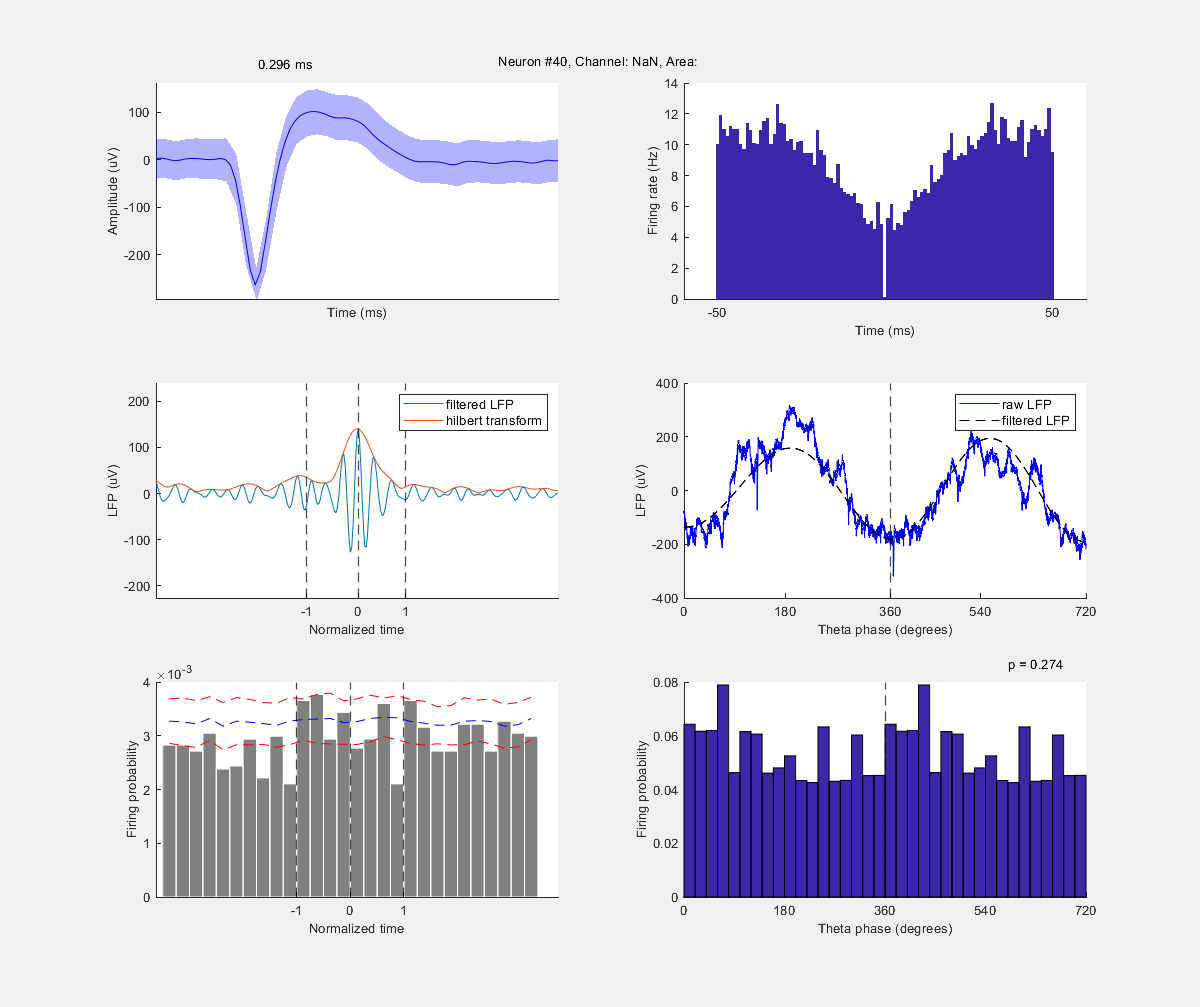

time = linspace(0,(num_samples./sample_rate_LFP),num_samples);
for c = 1:num_neurons
    close all
    gcf_manual=figure();
    set(gcf_manual,'Visible','on')
    % set(gcf,'defaultTextInterpreter','none');

    %% A. Plot waveform and trough to peak info
    subplot(3,2,1)

    plot(waveforms.time, waveforms.wave(c,:), 'b');
    hold on
    jbfill(waveforms.time_original, waveforms.mean_waveform(c,:)+waveforms.std_waveform(c,:), ...
        waveforms.mean_waveform(c,:)-waveforms.std_waveform(c,:), 'b', 'none', 0, 0.3);

    xlim([min(waveforms.time), max(waveforms.time)]);
    xticks([min(waveforms.time):0.25:max(waveforms.time)])
    xticklabels([spike_window(1):0.25:[spike_window(2)]])
    xlabel('Time (ms)')

    % scatter(waveforms(c).Peaks(2),waveforms(c).Amp(2),'*');
    % scatter(waveforms(c).Peaks(3),waveforms(c).Amp(3),'*');

    line_x = [waveforms.Peaks(c,2); waveforms.Peaks(c,3)];
    peak_waveform = max(waveforms.mean_waveform(c,:)+waveforms.std_waveform(c,:));
    line_y = [peak_waveform + 0.2*peak_waveform, peak_waveform + 0.2*peak_waveform];
    plot(line_x, line_y, 'Color', 'k', 'LineWidth', 0.7)

    text_x = (line_x(1) + line_x(2)) / 2;
    text_y = peak_waveform + 0.35*peak_waveform;
    text(text_x, text_y, sprintf('%.3f ms', waveforms.TroughtoPeak(c)), 'HorizontalAlignment', 'center', 'FontSize', 8)

    ylabel('Amplitude (uV)')
    ylim([min(waveforms.Amp(c,:))-30, max(waveforms.Amp(c,:))+60])
    set(gca,'XTick',[])
    set(gca,'box','off')

    %% B. Plot autocorrelogram
    subplot(3,2,2)

    % bin_size = 0.002;
    % isi1 = diff(spikes.times{spikes.cluster_index == c});
    % isi2 = diff(flip(spikes.times{spikes.cluster_index == c})); % calculate ISI in the opposite direction too
    % bin_edges_acg = -0.2:bin_size:0.2; % 200 ms
    % bin_centers = bin_edges_acg(1:end-1) + bin_size/2;
    % isi_bins = histcounts([isi1,isi2], bin_edges_acg);
    % bar(bin_centers, isi_bins);
    % ylabel('Spike counts')
    % xlabel('Time (s)')

    % Alternative ACG plot
    [ccg,t] = CCG({spikes.times{spikes.cluster_index == c}},[],'norm','rate','duration',0.1,'binSize',0.001); % -50 to +50 ms
    b = bar(t,ccg,'hist');
    b.EdgeColor = 'none';
    ylabel('Firing rate (Hz)')
    xticks([t(1) t(end)])
    xticklabels([t(1)*1000, t(end)*1000])
    xlabel('Time (ms)')
    set(gca,'box','off')
    acg{c} = ccg;

    %% C. Plot example SWR (right hemi)
    subplot(3,2,3)
    bin_size_swr = swr_firing{1}.around_bin_size;
    ripple_num = 1700;
    assert(strcmp(ripple_classes(ripple_num),'right'), 'This SWR was in the left hemisphere. Please select one from the right.')

    swr_window = find((ripple_timestamps(ripple_num,1) - 10*bin_size_swr) <= time & time <= (ripple_timestamps(ripple_num,end) + 10*bin_size_swr));
    plot(swr_window, LFP_filtered(swr_window, pyramidal_layer_right), 'DisplayName', 'filtered LFP');
    hold on
    plot(swr_window, LFP_filtered_hilbert(swr_window, pyramidal_layer_right), 'DisplayName', 'hilbert transform');
    max_idx = find(LFP_filtered_hilbert(swr_window, pyramidal_layer_right)==max(LFP_filtered_hilbert(swr_window, pyramidal_layer_right))) + swr_window(1);
    xline(max_idx, '--k', 'LineWidth', 1, 'HandleVisibility','off'); % peak
    [~,start_idx] = min(abs(time - ripple_timestamps(ripple_num,1)));
    xline(start_idx, '--k', 'LineWidth', 1, 'HandleVisibility','off'); % start
    [~,end_idx] = min(abs(time - ripple_timestamps(ripple_num,end)));
    xline(end_idx, '--k', 'LineWidth', 1, 'HandleVisibility','off'); % end
    xlim([min(swr_window), max(swr_window)]);
    xticks([start_idx, max_idx, end_idx]);
    xticklabels({'-1', '0', '1'});
    xlabel('Normalized time');
    ylim([min(LFP_filtered(swr_window, pyramidal_layer_right))-100, max(LFP_filtered(swr_window, pyramidal_layer_right))+100])
    ylabel('LFP (uV)')
    set(gca,'box','off')
    legend

    %% D. Plot example theta segment and theta phase from data (right hemi)
    subplot(3,2,4)
    theta_window = new_theta_windows(50) : (new_theta_windows(50) + sample_rate); % 1 sec window

    [troughs, troughs_idx] = findpeaks(-theta_info.thetaPhase(theta_window,2)); %islocalmin(theta_info.thetaPhase(theta_window,2));
    % troughs_idx = find(troughs==1);
    [peaks, peaks_idx] = findpeaks(theta_info.thetaPhase(theta_window(troughs_idx(1):end),2)); %islocalmax(theta_info.thetaPhase(theta_window(troughs_idx(1):end),2));
    % peaks_idx = find(peaks==1) + troughs_idx(1);
    theta_short_window = theta_window(troughs_idx(1):troughs_idx(3)); %peaks_idx(2));
    ticks_idx = sort([troughs_idx(1:3); peaks_idx(1:2)]);
    % ticks_idx = [find(islocalmin(theta_info.thetaLFP(theta_short_window)) | islocalmax(theta_info.thetaLFP(theta_short_window))), length(theta_short_window)];

    plot(theta_short_window, LFPFromSelectedChannels(2,theta_short_window), 'b', 'DisplayName', 'raw LFP');
    hold on
    plot(theta_short_window, theta_info.thetaLFP(theta_short_window,2), '--k', 'DisplayName', 'filtered LFP');
    xline(theta_window(ticks_idx(3)), '--k', 'LineWidth', 1, 'HandleVisibility','off');
    ylabel('LFP (uV)')
    xlabel('Theta phase (degrees)')
    xticks(theta_window(ticks_idx))
    xticklabels([0 180 360 540 720])
    xlim([min(theta_short_window), max(theta_short_window)])
    set(gca,'box','off')
    legend

    % yyaxis right
    % plot(theta_short_window, thetaPhase(theta_short_window,1)*100, 'r', 'DisplayName', 'theta phase');
    % ylabel('Phase (degrees)')
    % yticks([-180 -90 0 90 180]*100)
    % yticklabels([0 90 180 270 360])

    %% E. Plot histogram of firing probabilities around SWR
    subplot(3,2,5)
    h = bar(1:28, [swr_firing{c}.first_firing_prob, swr_firing{c}.firing_prob_start, swr_firing{c}.firing_prob_end, swr_firing{c}.second_firing_prob], ...
        'hist');
    set(h, 'FaceColor', [0.5 0.5 0.5], 'EdgeColor', 'white');
    hold on
    p1 = plot(1:28, swr_firing{c}.mean_firing_prob_shuffled, '--b', 'LineWidth', 0.5); %, 'DisplayName', 'mean in non-theta/non-SWR');
    p2 = plot(1:28, swr_firing{c}.mean_firing_prob_shuffled + swr_firing{c}.std_firing_prob_shuffled, '--r', 'LineWidth', 0.5); %, 'DisplayName', 'mean +/- std in non-theta/non-SWR');
    p3 = plot(1:28, swr_firing{c}.mean_firing_prob_shuffled - swr_firing{c}.std_firing_prob_shuffled, '--r', 'LineWidth', 0.5); %, 'HandleVisibility','off');
    xticks([10.5, 14.5, 18.5]);
    xticklabels({'-1', '0', '1'});
    xlabel('Normalized time');
    ylabel('Firing probability');
    hold on
    xline(10.5, '--k', 'LineWidth', 1, 'HandleVisibility','off'); % start
    xline(14.5, '--k', 'LineWidth', 1, 'HandleVisibility','off'); % peak
    xline(18.5, '--k', 'LineWidth', 1, 'HandleVisibility','off'); % end
    % legend([p1,p2])
    set(gca,'Layer','top');
    set(gca,'box','off')

    %% F. Plot histogram of firing probabilities for theta phases
    subplot(3,2,6)
    bin_centers_theta = bin_edges_theta(1:end-1) + (bin_edges_theta(2)-bin_edges_theta(1))/2;
    bar([bin_centers_theta, bin_centers_theta+360], [theta_firing.firing_prob(c,:), theta_firing.firing_prob(c,:)], 'hist');
    xticks(min(bin_edges_theta):180:max(bin_edges_theta+360));
    xticklabels(0:180:720); % shift the labels by 180 deg
    xlim([min(bin_edges_theta) max(bin_edges_theta+360)]);
    xlabel('Theta phase (degrees)')
    ylabel('Firing probability');
    hold on
    xline(bin_edges_theta(end), '--k', 'LineWidth', 1, 'HandleVisibility','off');
    set(gca,'box','off')

    % Plot p-value
    if theta_firing.p_values(c) >= 0.001
        p_text = sprintf('p = %.3f', theta_firing.p_values(c));
    else
        p_text = sprintf('p < 0.001');
    end
    text(450, max(theta_firing.firing_prob(c,:)) + 0.1*max(theta_firing.firing_prob(c,:)), ...
        p_text, 'HorizontalAlignment', 'center', 'FontSize', 8)

    %% Extra channel and neuron info for title
    area = fr_map_info.location(fr_map_info.site == siteMap(clusterSites(c)));
    if ~isempty(area) % visible electrode
        textArray = ['Neuron #' num2str(c) ', Channel: ' num2str(fr_map_info.channel(c)) ', Area: ' area{1} ', Firing rate: ' sprintf('%.2g', fr_map_info.firing_rate(c)) ' Hz'];
    else
        textArray = ['Neuron #' num2str(c) ', Channel: ' num2str(fr_map_info.site(c)-1) ', Firing rate: ' sprintf('%.2g', fr_map_info.firing_rate(c)) ' Hz'];
    end

    if iscell(textArray)
        sgtitle(strjoin(textArray, ''), 'FontSize',10);
    else
        sgtitle(textArray, 'FontSize',10);
    end

    set(findall(gcf_manual,'-property','FontName'),'FontName','Arial');
    set(findall(gcf_manual,'-property','FontSize'),'FontSize',10);
    set(findall(gcf_manual, 'type', 'text'), 'Interpreter', 'none');
    % set(findall(gcf, 'Type', 'text'), 'Interpreter','none');
    % set(findall(gcf, 'Type', 'axes'), 'TickLabelInterpreter','none');
    % set(findall(gcf, 'Type', 'legend'), 'Interpreter','none');
    % set(findall(gcf, 'Type', 'sgtitle'), 'Interpreter','none');
    % set(findall(gcf, 'Type', 'Text'), 'Interpreter','none');

    set(gcf_manual,'defaultTextInterpreter','none');
    set(groot, 'defaultTextInterpreter', 'none');

    fig=gcf_manual;

    fig.PaperUnits = 'points';
    fig.Position = [100,100,1200,1600];
    fig.Renderer = 'Painters';
    saveas(fig, fullfile(plotpath, ['newSort_cell_alldata_theta20_' num2str(c)]), 'fig');
    % saveas(fig, fullfile(plotpath, ['cell_alldata_theta20_' num2str(c)]), 'svg');
    saveas(fig, fullfile(plotpath, ['newSort_cell_alldata_theta20_' num2str(c) '.png']), 'png');
    saveas(fig, fullfile(plotpath, ['newSort_cell_alldata_theta20_' num2str(c) '.eps']), 'epsc');
  
end

% %% Save the figure data
% figure.A.time = waveforms.time;
% figure.A.time_original = waveforms.time_original;
% figure.A.waveform_wave = waveforms.wave;
% figure.A.spike_window = spike_window;
% figure.A.mean_waveform = waveforms.mean_waveform;
% figure.A.std_waveform = vstd_waveform;
% figure.A.peaks_amplitude = waveforms.Amp;
% figure.A.peaks_idx = waveforms.Peaks;
% figure.A.trough2peak = waveforms.TroughtoPeak;
%
% figure.B.acg = acg;
% figure.B.time = t;
% figure.B.acg_duration = 0.1;
% figure.B.acg_bin_size = 0.01;
%
% figure.C.ripple_number = ripple_num;
% figure.C.ripple_timestamps = ripple_timestamps(ripple_num,:);
% figure.C.corr_window = swr_window;
% figure.C.LFP_filtered = LFP_filtered(swr_window, pyramidal_layer_right);
% figure.C.LFP_channel = pyramidal_layer_right;
% figure.C.bin_size_aroundSWRs = bin_size_swr;
%
% figure.D.theta_segment_time = theta_short_window ./ sample_rate;
% figure.D.thetaLFP = thetaLFP(theta_short_window,2);
% figure.D.LFP = LFPFromSelectedChannels(2,theta_short_window);
% figure.D.thetaPhase = thetaPhase(theta_short_window);
%
% figure.E.before_SWR_firing_prob = swr_firing.first_firing_prob;
% figure.E.after_SWR_firing_prob = swr_firing.second_firing_prob;
% figure.E.minusOne2zero_firing_prob = swr_firing.firing_prob_start;
% figure.E.zeros2one_firing_prob = swr_firing.firing_prob_end;
% figure.E.bin_size_aroundSWRs = bin_size_swr;
%
% figure.F.bin_edges = bin_edges_theta;
% figure.F.bin_centers = bin_centers_theta;
% figure.F.xticks = min(bin_edges_theta):180:max(bin_edges_theta+360);
% figure.F.xticklabels = 0:180:720;
% figure.F.firing_prob = theta_firing.firing_prob;
% figure.F.bin_size = 360/num_bins_theta;
%
% save(fullfile(basepath, [sessname '.figure.mat']), 'figure');